Datta Figure 2.3.2 (This will plot 2 figures. The 1st figure is energy level vs. quantum number and the 2nd figure is probability vs. distance)

%Constants (All MKS, except energy which is in eV)
hbar=1.055e-34 %Reduced Planck's Constant = h/2pi

hbar = 1.0550e-34

m=9.110e-31 %Mass of the electron

m = 9.1100e-31

epsil=8.854e-12 %??

epsil = 8.8540e-12

q=1.602e-19 %Charge of the electron

q = 1.6020e-19

%Lattice
Np=100 %No. of lattice sites

Np = 100

a=1e-10 %Lattice size

a = 1.0000e-10

X=a*[1:1:Np] %Creating a vector 1 to 100, X coordinates in well

X = 1.0e-08 *

    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900    0.5000


t0=(hbar^2)/(2*m*(a^2))/q %Grouping constants to make another constant

t0 = 3.8132

L=a*(Np+1) %Well width

L = 1.0100e-08

T=(2*t0*diag(ones(1,Np)))-(t0*diag(ones(1,Np-1),1))-(t0*diag(ones(1,Np-1),-1)) %??

T =     7.6265   -3.8132         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -3.8132    7.6265   -3.8132         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

[V,D]=eig(T) %T is Hamiltonian (Finite Different Method) - Why do we want Eigenvalues of Hamiltonian?

V =    -0.0044   -0.0087    0.0131    0.0175    0.0218   -0.0261    0.0304    0.0347    0.0389   -0.0431   -0.0472    0.0513    0.0554   -0.0594   -0.0633    0.0672    0.0710   -0.0747   -0.0784    0.0820    0.0855   -0.0890   -0.0923    0.0956   -0.0987   -0.1018   -0.1048    0.1076   -0.1104   -0.1131   -0.1156    0.1181   -0.1204   -0.1226    0.1247    0.1266    0.1285   -0.1302   -0.1318    0.1333    0.1346   -0.1358   -0.1369    0.1379    0.1387   -0.1393   -0.1399    0.1403    0.1406   -0.1407
   -0.0087   -0.0175    0.0261    0.0347    0.0431   -0.0513    0.0594    0.0672    0.0747   -0.0820   -0.0890    0.0956    0.1018   -0.1076   -0.1131    0.1181    0.1226   -0.1266   -0.1302    0.1333    0.1358   -0.1379   -0.1393    0.1403   -0.1407   -0.1406   -0.1399    0.1387   -0.1369   -0.1346   -0.1318    0.1285   -0.1247   -0.1204    0.1156    0.1104    0.1048   -0.0987   -0.0923    0.0855    0.0784   -0.0710   -0.0633    0.0554    0.0472   -0.0389   -0.0304    0.0218    0.0131   -0

D =     0.0037         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.0148         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

D=diag(D) %Matrix conversion to vector

D =     0.0037
    0.0148
    0.0332
    0.0590
    0.0920
    0.1324
    0.1801
    0.2349
    0.2969
    0.3660


[Enum,ind]=sort(D) %Numerical values of energy levels

Enum =     0.0037
    0.0148
    0.0332
    0.0590
    0.0920
    0.1324
    0.1801
    0.2349
    0.2969
    0.3660


ind =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


E1=D(ind(1))

E1 = 0.0037

psi1=abs(V(:,ind(1)))

psi1 =     0.0044
    0.0087
    0.0131
    0.0175
    0.0218
    0.0261
    0.0304
    0.0347
    0.0389
    0.0431


P1=psi1.*conj(psi1) %psi is the wavefunction %conj stands for conjugate

P1 =     0.0000
    0.0001
    0.0002
    0.0003
    0.0005
    0.0007
    0.0009
    0.0012
    0.0015
    0.0019


E2=D(ind(25))

E2 = 2.1920

psi2=abs(V(:,ind(25))) %V = Wavefunction, n=25

psi2 =     0.0987
    0.1407
    0.1018
    0.0044
    0.0956
    0.1406
    0.1048
    0.0087
    0.0923
    0.1403


P2=psi2.*conj(psi2) %Probability distribution

P2 =     0.0097
    0.0198
    0.0104
    0.0000
    0.0091
    0.0198
    0.0110
    0.0001
    0.0085
    0.0197



%Anaylytical Eigenvalues
Ean=(((hbar*pi)^2)/(2*m*(L^2))/q)*[1:Np].*[1:Np] %Lab notes formula

Ean =     0.0037    0.0148    0.0332    0.0590    0.0922    0.1328    0.1808    0.2361    0.2988    0.3689    0.4464    0.5313    0.6235    0.7231    0.8301    0.9445    1.0662    1.1954    1.3319    1.4757    1.6270    1.7857    1.9517    2.1251    2.3058    2.4940    2.6895    2.8925    3.1028    3.3204    3.5455    3.7779    4.0177    4.2649    4.5195    4.7814    5.0507    5.3274    5.6115    5.9030    6.2018    6.5080    6.8216    7.1426    7.4710    7.8067    8.1498    8.5003    8.8582    9.2234



hold on
%h=plot(Enum,'bx');% Part (a)
%h=plot(Ean,'b');% Part (a)
h=plot(P1,'b')

h =   Line with properties:

              Color: [0 0 1]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 65 66 67 68 69 70 71 72 73 74 ... ] (1x100 double)
              YData: [1.9153e-05 7.6536e-05 1.7193e-04 3.0496e-04 4.7512e-04 6.8174e-04 9.2403e-04 0.0012 0.0015 0.0019 0.0022 0.0026 0.0031 0.0035 0.0040 0.0045 0.0050 0.0056 0.0061 0.0067 0.0073 0.0079 0.0085 0.0091 0.0097 0.0104 ... ] (1x100 double)

  Show <a href="matlab:if exist('h', 'var'), matlab.graphics.internal.getForDisplay('h', h, 'matlab.graphics.chart.primitive.Line'), else, matlab.graphics.internal.getForDisplay('h'), end">all properties<

h1=plot(P2,'b')

h1 =   Line with properties:

              Color: [0 0 1]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 65 66 67 68 69 70 71 72 73 74 ... ] (1x100 double)
              YData: [0.0097 0.0198 0.0104 1.9153e-05 0.0091 0.0198 0.0110 7.6536e-05 0.0085 0.0197 0.0116 1.7193e-04 0.0079 0.0196 0.0122 3.0496e-04 0.0073 0.0194 0.0128 4.7512e-04 0.0067 0.0192 0.0134 6.8174e-04 0.0061 0.0190 0.0139 ... ] (1x100 double)

  Show all pro

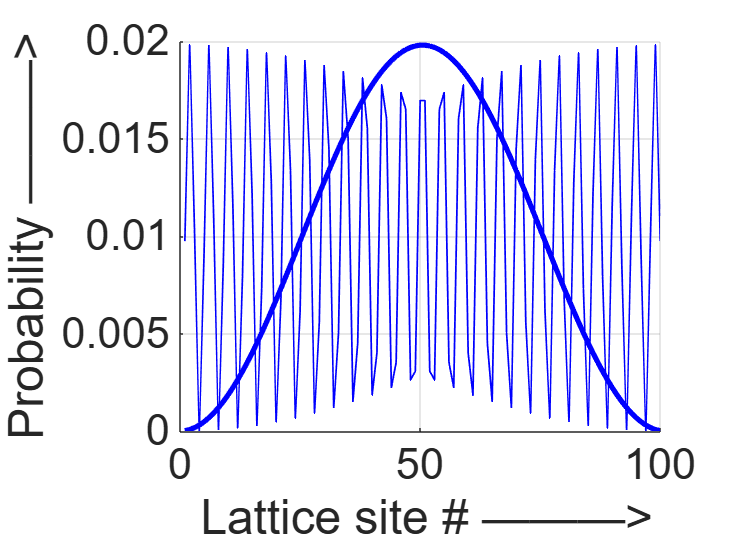

set(h,'linewidth',[3.0])
set(h1,'linewidth',[1.0])
set(gca,'Fontsize',[25])
%xlabel(' Eigenvalue Number , alpha --->')
%ylabel(' E (eV) ---> ')
xlabel(' Lattice site # ———>')
ylabel(' Probability ———> ')
grid on